# Fluorophores from the literature

Many people treat the emission matrix of various fluorophores as 1-dimensional.  In that case changing the excitation wavelength simply scales the emission.  Or, perhaps, there is a scaling coupled with restriction that the emissions must be longer wavelength than the excitation (lower diagonal constraint).

Joyce has collected data from the literature, which we will share here. The papers are in Paperpile.  These different authors purport to measure the same fluorophore. But none of these is very secure, they differ between one another.

I am not sure the list in here is exhaustive.  Could check if we added more.

Also, I am not sure what happened to Palero data, which used to be here but is now gone.  Maybe we judged it to be wrong in some way.

See also:  

    s_oeBloodFluorophoreBasis.

ieInit;
wave = 380:780;
normWave = 500;
yscale = 'linear';
ylim = [10^-2, 4];
xlim = [350 700];

## **Elastin **

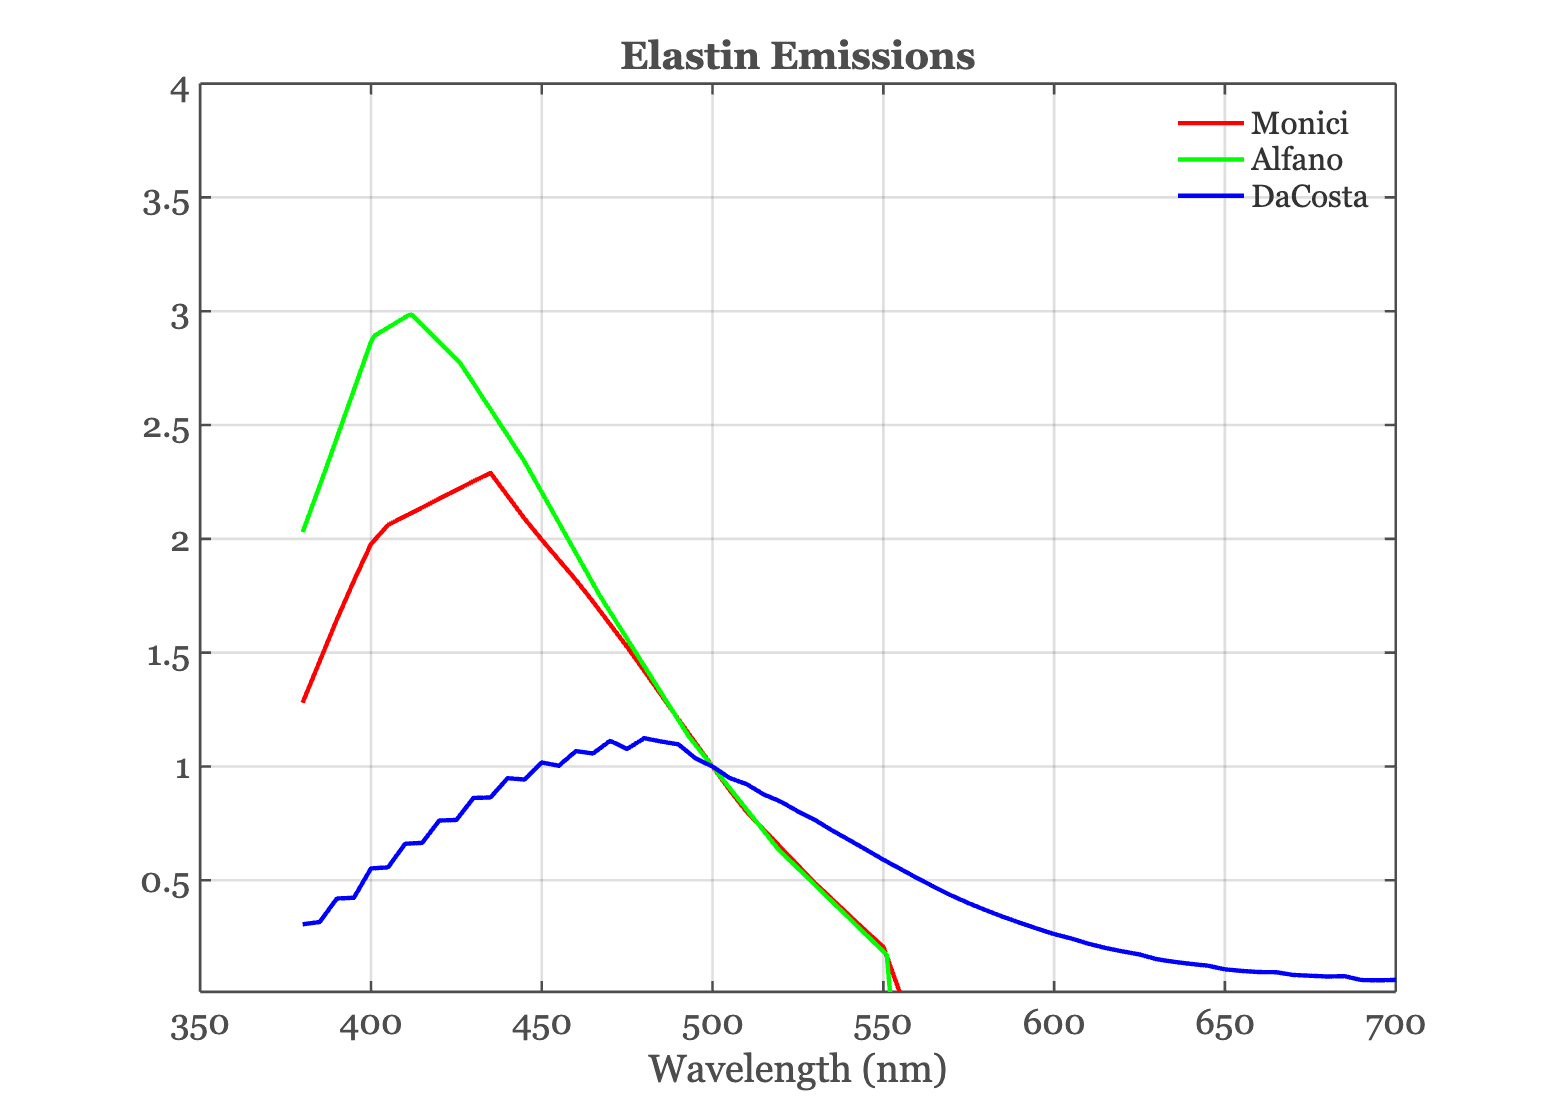

elastinFiles = {'ElastinMonici','ElastinAlfano','elastin_webfluor'};
nFiles = numel(elastinFiles);
data = zeros(numel(wave),nFiles);
for ii=1:nFiles
    tmp = fiReadFluorophore(elastinFiles{ii},'wave',wave);
    data(:,ii) = fluorophoreGet(tmp,'normalized emission','wave',wave);
    data(:,ii) = data(:,ii)/data(wave == normWave,ii);
end

colors = lines(size(data, 2)); % Get a set of distinct colors
ieFigure;
for ii = 1:size(data, 2)
    plot(wave, data(:, ii), 'Color', colors(ii, :),'LineWidth',2); hold on;
end
hold off; % Release hold

title('Elastin Emissions');
legend({'Monici','Alfano','DaCosta'});
grid on; xlabel('Wavelength (nm)');
set(gca,'yscale',yscale,'ylim',ylim,'xlim',xlim);

## **Collagen**

Brief paper that points out the variability in excitation and emission spectra for collagen described in the literature:  Saletnik, Ł., & Wesołowski, R. (2022). Fluorescent spectroscopy of collagen as a diagnostic tool in medicine. *Journal of Medical Science*, *91*(1), e584-e584.

collagenFiles = {'CollagenLin','CollagenWuQu','CollagenMonici','CollagenAlfano','collagen1-smooth','collagen5','collagen7'};

wave = 380:5:780;
clear collagen
data = zeros(numel(wave),numel(collagenFiles));
for ii=1:numel(collagenFiles)
    tmp = fiReadFluorophore(collagenFiles{ii},'wave',wave);
    data(:,ii) = fluorophoreGet(tmp,'normalized emission','wave',wave);
    data(:,ii) = data(:,ii)/data(wave == normWave,ii);
end

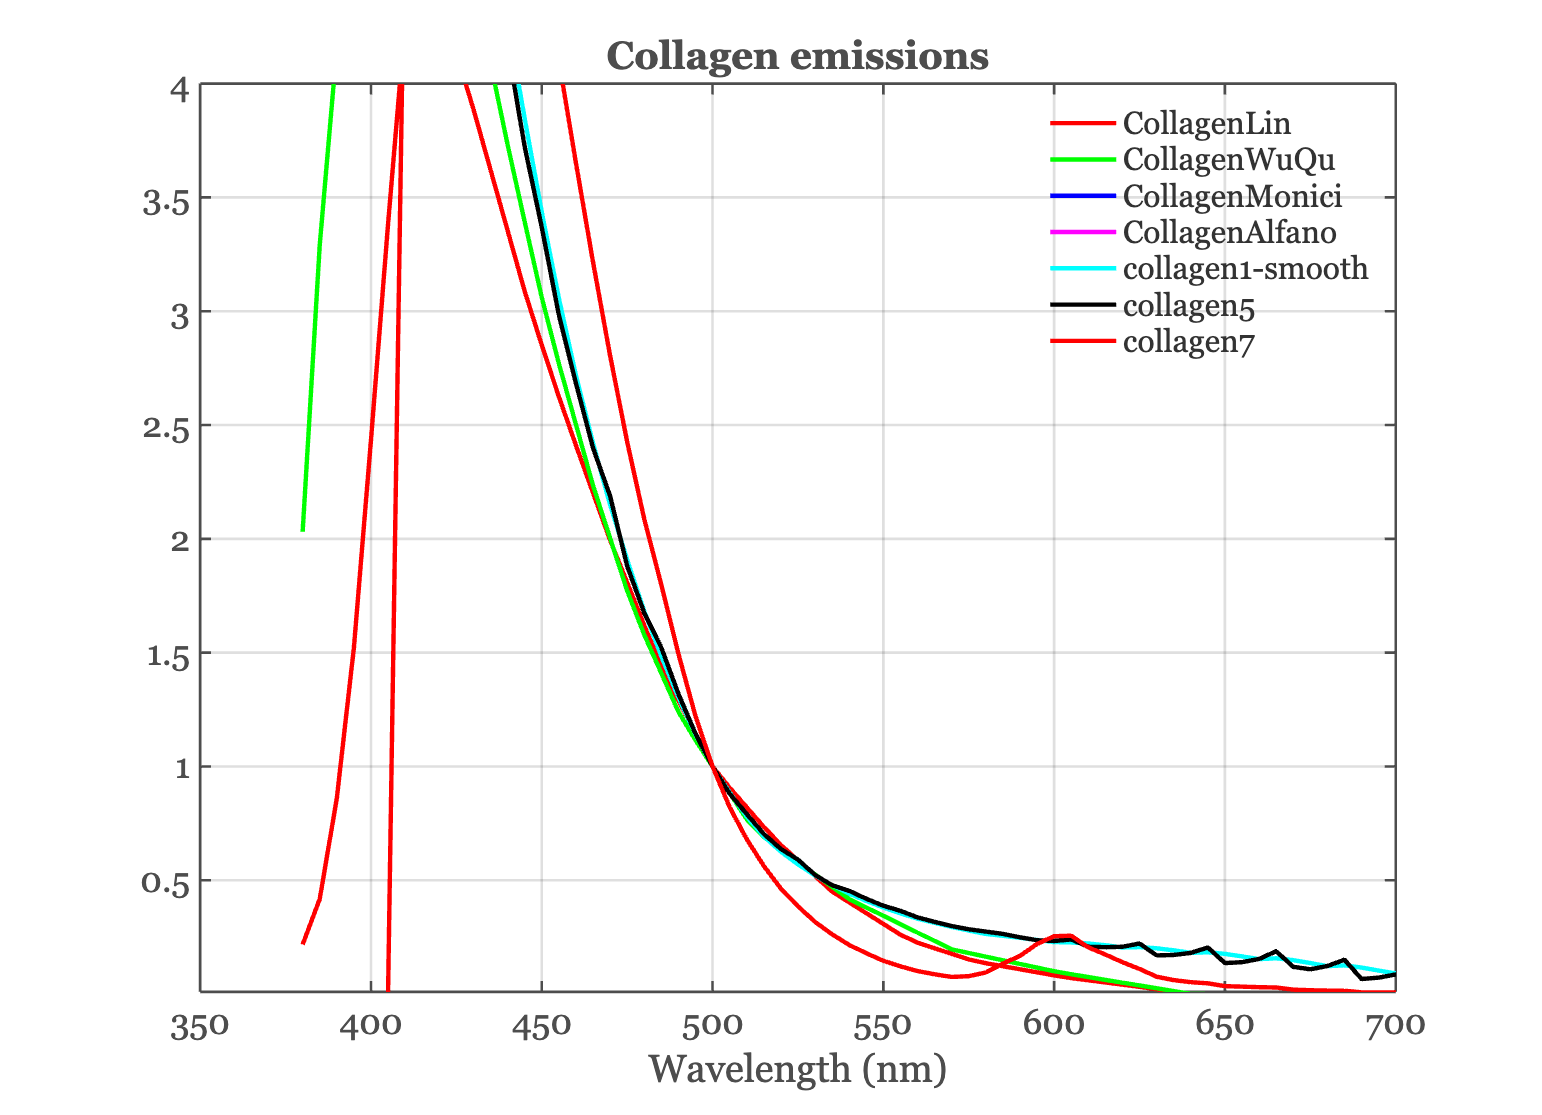

ieNewGraphWin;
colors = lines(size(data, 2)); % Get a set of distinct colors
for ii = 1:size(data, 2)
    plot(wave, data(:, ii), 'Color', colors(ii, :),'LineWidth',2); hold on;
end
hold off; % Release hold
title('Collagen emissions');
legend(collagenFiles);
grid on; xlabel('Wavelength (nm)');
set(gca,'yscale',yscale,'ylim',ylim,'xlim',xlim);

## **Keratin**

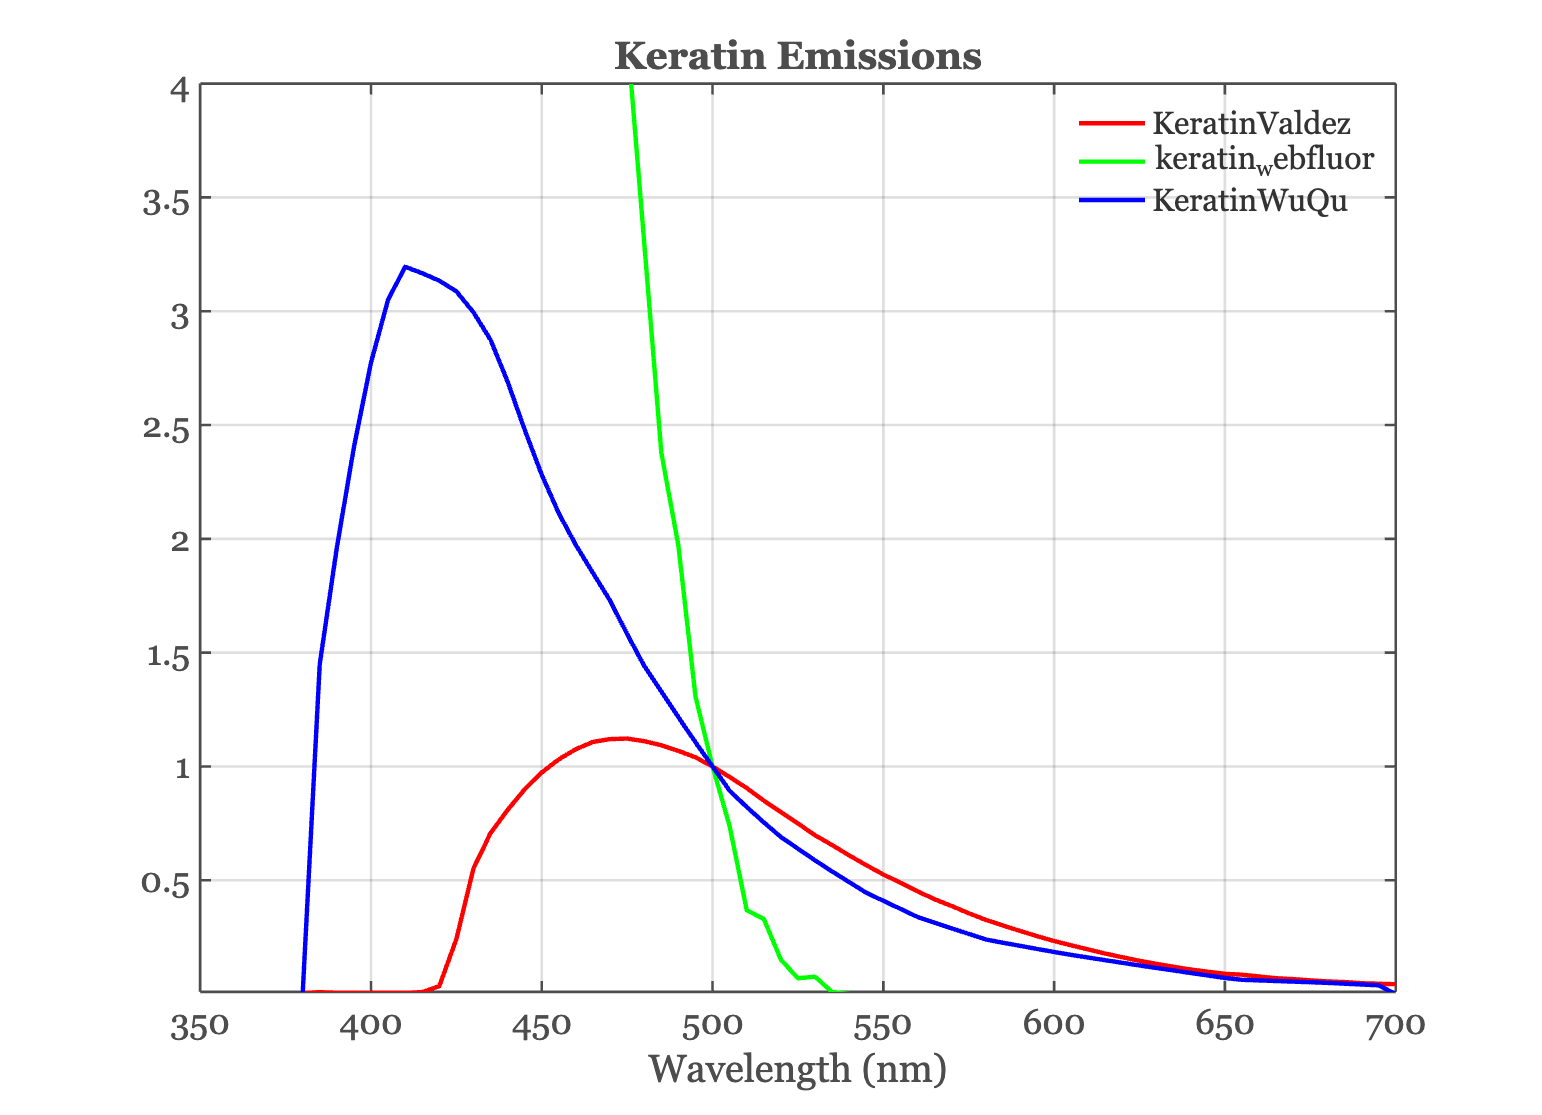

keratinFiles = {'KeratinValdez','keratin_webfluor','KeratinWuQu'};
clear keratin
nFiles = numel(keratinFiles);
data = zeros(numel(wave),nFiles);
for ii=1:nFiles
    tmp = fiReadFluorophore(keratinFiles{ii},'wave',wave);
    data(:,ii) = fluorophoreGet(tmp,'normalized emission','wave',wave);
    data(:,ii) = data(:,ii)/data(wave == normWave,ii);
end

ieNewGraphWin;
colors = lines(size(data, 2)); % Get a set of distinct colors
for ii = 1:size(data, 2)
    plot(wave, data(:, ii), 'Color', colors(ii, :),'LineWidth',2); hold on;
end
hold off; % Release hold
set(gca,'yscale',yscale,'ylim',ylim,'xlim',xlim);
legend(keratinFiles);
title('Keratin Emissions'); grid on; xlabel('Wavelength (nm)');

## **FAD**

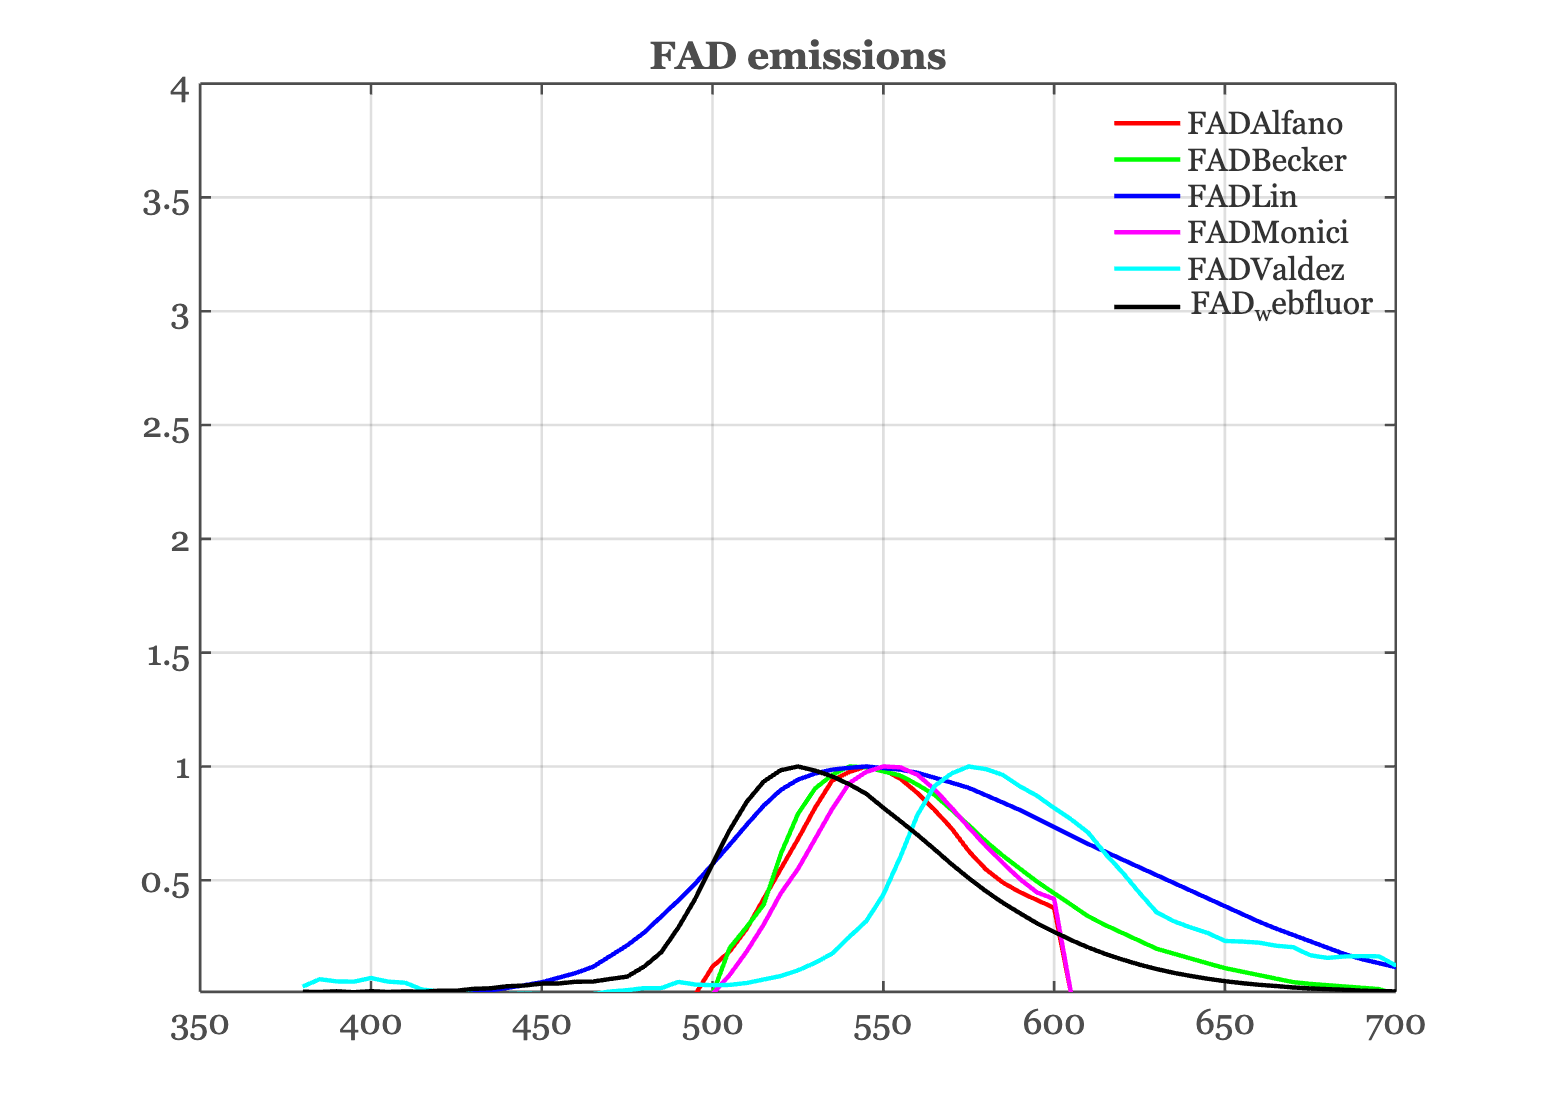

FADFiles = {'FADAlfano','FADBecker','FADLin','FADMonici','FADValdez','FAD_webfluor'};
nFiles = numel(FADFiles);
data = zeros(numel(wave),nFiles);
for ii=1:nFiles
    tmp = fiReadFluorophore(FADFiles{ii},'wave',wave);
    data(:,ii) = fluorophoreGet(tmp,'normalized emission','wave',wave);
    %data(:,ii) = data(:,ii)/data(wave == 520,ii);
end

ieFigure;
colors = lines(size(data, 2)); % Get a set of distinct colors
for ii = 1:size(data, 2)
    plot(wave, data(:, ii), 'Color', colors(ii, :),'LineWidth',2); hold on;
end
set(gca,'yscale',yscale,'ylim',ylim,'xlim',xlim);
hold off; % Release hold
legend(FADFiles);
title('FAD emissions'); grid on;

## **NADH**

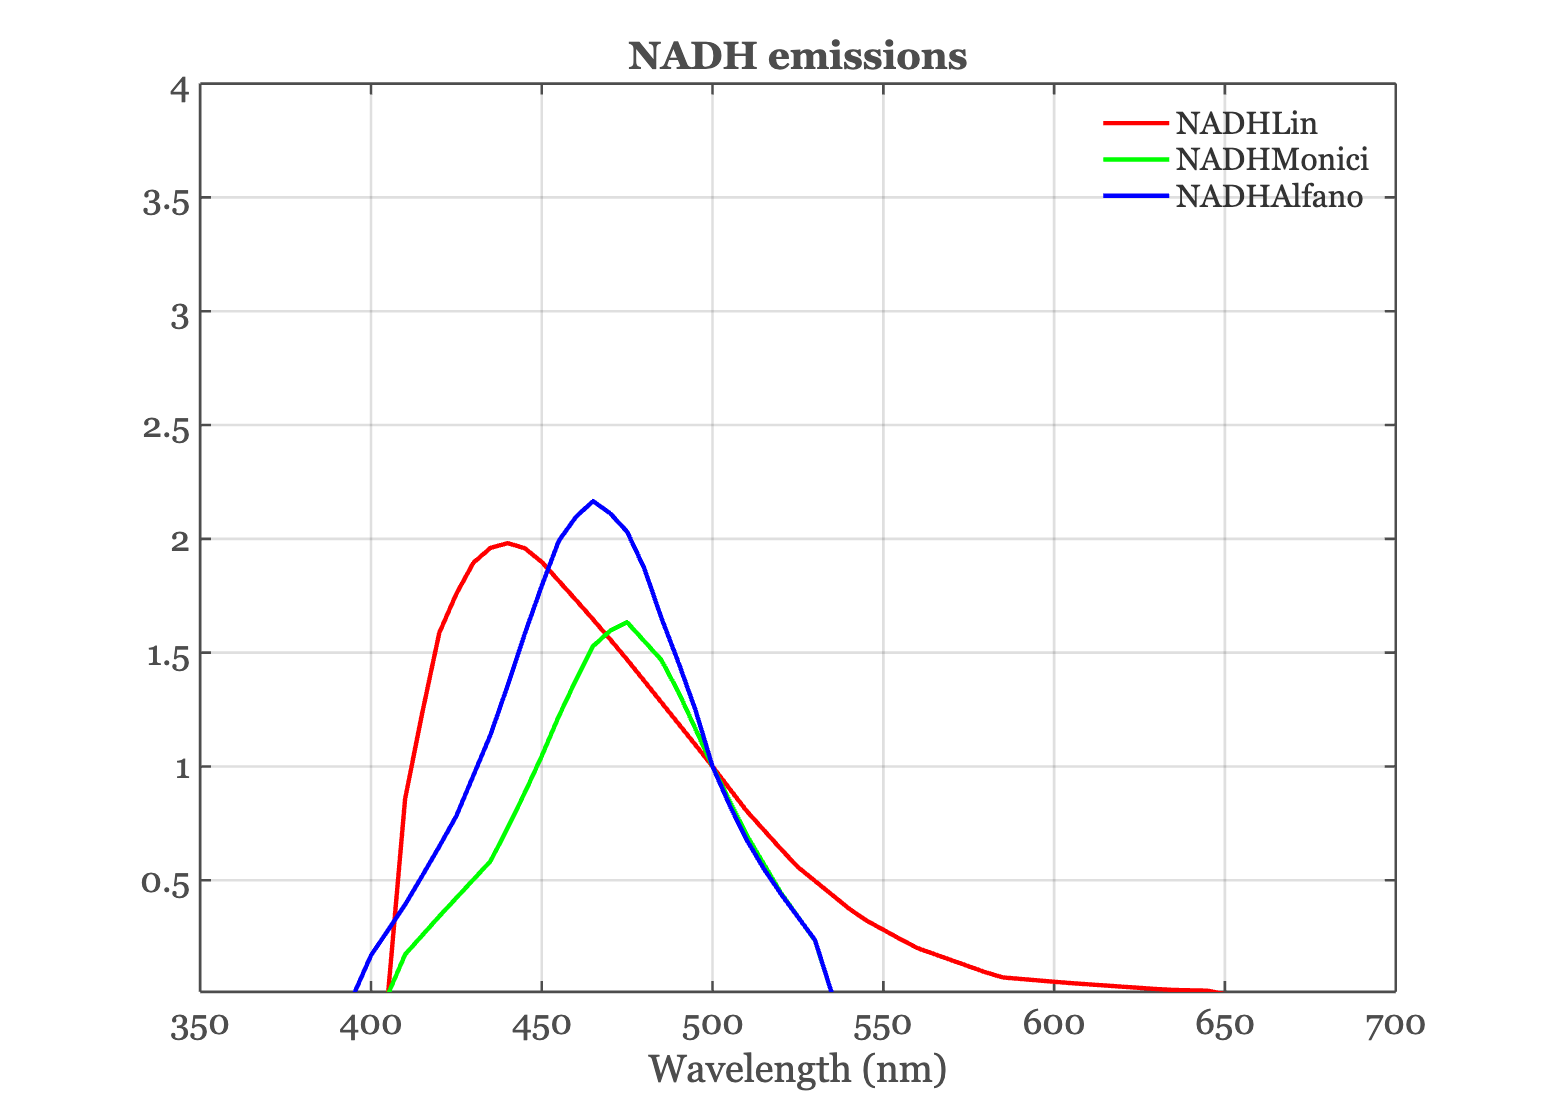

NADHFiles = {'NADHLin','NADHMonici','NADHAlfano'};
nFiles = numel(NADHFiles);
data = zeros(numel(wave),nFiles);
for ii=1:nFiles
    tmp = fiReadFluorophore(NADHFiles{ii},'wave',wave);
    data(:,ii) = fluorophoreGet(tmp,'normalized emission','wave',wave);
    data(:,ii) = data(:,ii)/data(wave == normWave,ii);
end

ieNewGraphWin;
colors = lines(size(data, 2)); % Get a set of distinct colors
for ii = 1:size(data, 2)
    plot(wave, data(:, ii), 'Color', colors(ii, :),'LineWidth',2); hold on;
end
hold off; % Release hold
legend(NADHFiles);
set(gca,'yscale',yscale,'ylim',ylim,'xlim',xlim);
title('NADH emissions'); grid on;
grid on; xlabel('Wavelength (nm)');

## **Porphyrins**

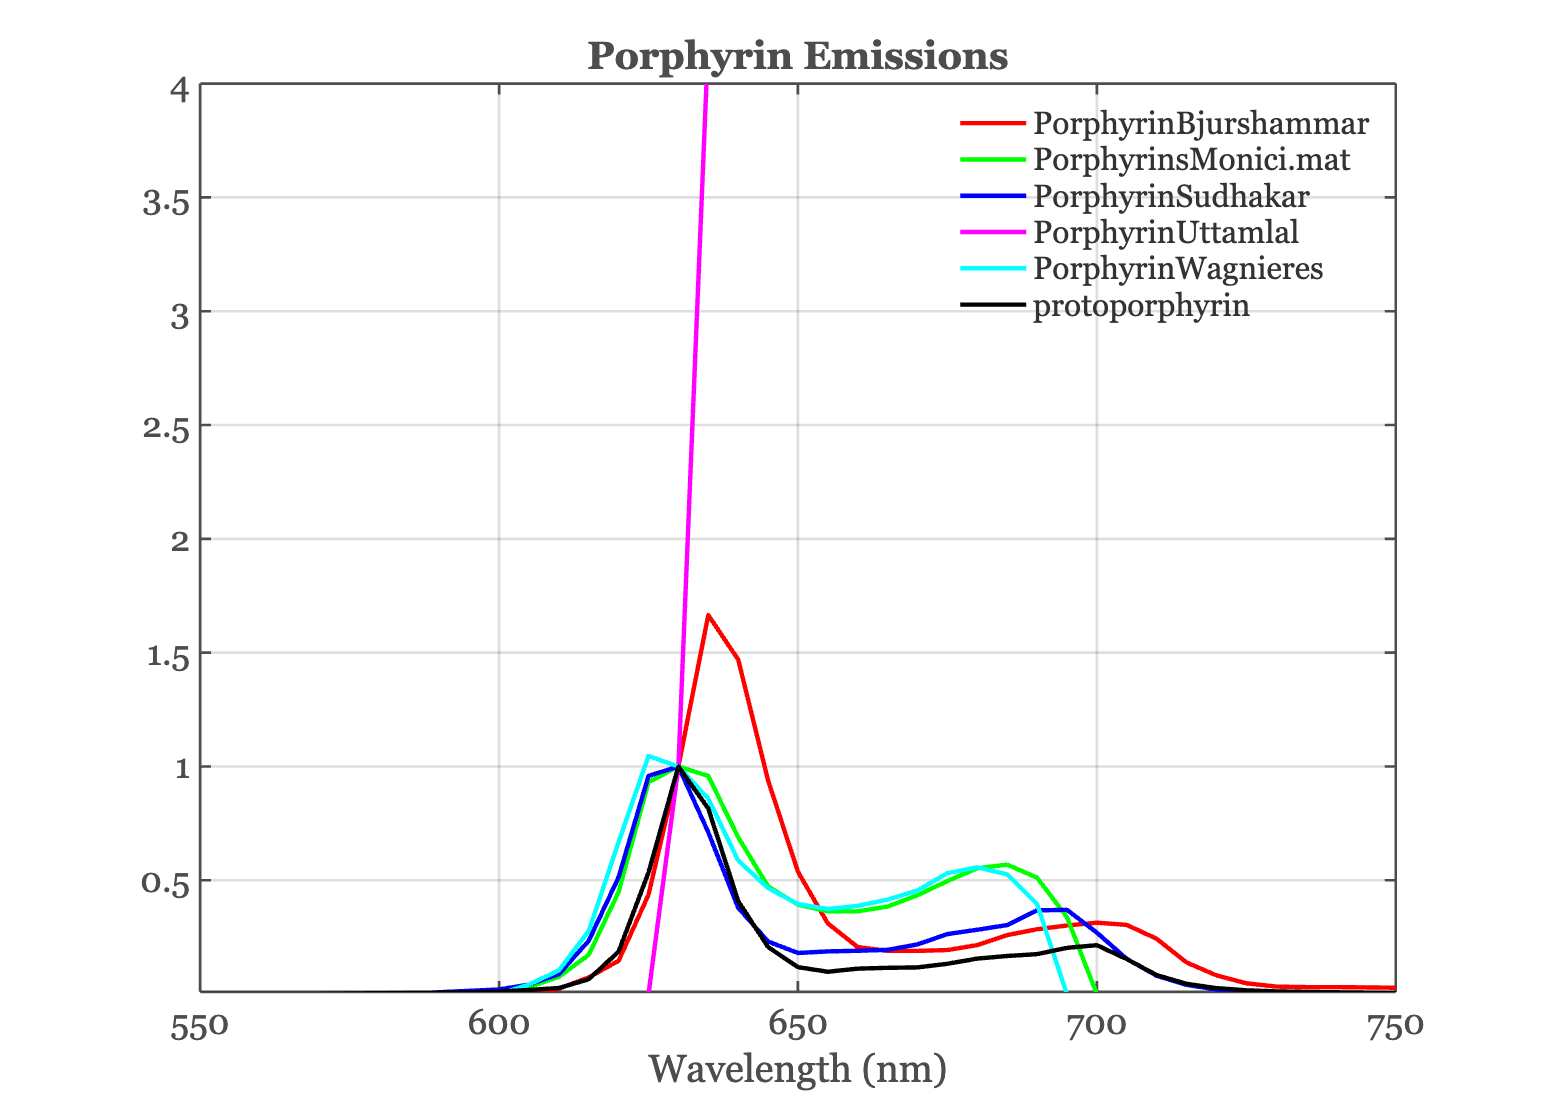

porphyrinFiles = {'PorphyrinBjurshammar','PorphyrinsMonici.mat','PorphyrinSudhakar',...
    'PorphyrinUttamlal','PorphyrinWagnieres','protoporphyrin'};
data = zeros(numel(wave),numel(porphyrinFiles));

for ii=1:numel(porphyrinFiles)
    tmp = fiReadFluorophore(porphyrinFiles{ii},'wave',wave);
    data(:,ii) = fluorophoreGet(tmp,'normalized emission','wave',wave);
    data(:,ii) = data(:,ii)/data(wave == 630,ii);    
end

colors = lines(size(data, 2)); % Get a set of distinct colors
for ii = 1:size(data, 2)
    plot(wave, data(:, ii), 'Color', colors(ii, :),'LineWidth',2); hold on;
end
hold off; % Release hold

title('Porphyrin Emissions');
legend(porphyrinFiles);
grid on; xlabel('Wavelength (nm)');
set(gca,'yscale',yscale,'ylim',ylim,'xlim',[550 750]);